# Place Field Detection 

This script is created to detect place fields from a 2D open field. Note that [buzcode](https://github.com/buzsakilab/buzcode/tree/dev) is needed (needs to be installed and compiled).

This script does the following: 

- Using **position_preprocessing_dlc g**et the tracking (.csv file with positions of the animal in the 2D open field) and the analog input and so the timestamps of the video frames 

- Using **loadSpikes **detect spikes and times and assign them to the cluster they are coming from 

- Using **bz_firingMapAvg** detect the firing rates of each neuron for each position bin. We can optionally plot thefiring rate maps and the firing superimposed on the trajectory of the animal. 

- Using **getPlaceFields **detect whether there are any place fields. Optionally plot the place fields. 

February 2023, Athina Apostolelli 

## Set parameters 

basepath = 'D:\Rat_Recording\rEO_06\10_240314_131027'; % change accordingly
cd(basepath)
project = 'MRI_project2-Athina-2024-02-09' % generated by the DLC code

project = 'MRI_project2-Athina-2024-02-09'

plotMaps = true;
plotTraj = true;
plotFields = true;
mazeSize = [1430,1430];

## Get tracking from DeepLabCut

You need to go into the following script to change the directory of the recordings. Note that the video and the DLC csv files need to be in the same directory as the recording files. This is where the tracking output will be saved. 

Reading Intan Technologies RHD2000 Data File, Version 3.0

Found 128 amplifier channels.
Found 6 auxiliary input channels.
Found 0 supply voltage channels.
Found 1 board ADC channel.
Found 0 board digital input channels.
Found 0 board digital output channels.
Found 0 temperature sensor channels.

Header file contains no data.  Amplifiers were sampled at 20.00 kS/s.

Done!  Elapsed time: 0.0 seconds
Extracted waveform information is now available in the MATLAB workspace.
Type 'whos' to see variables.

Number of TTLs for frames on analog input: 90008
Number of frames for the video files: 90000 - FrameRate: 50
frame difference: #TTLs - #videoFrames: 8
cage size is: 1430 x 1430mm
1.) Open video file: 9.avi
2.) Please select the corners of cage (base)!
3.) transformation matrix is DONE!
4.) transfrom the image
5.) plotting figures


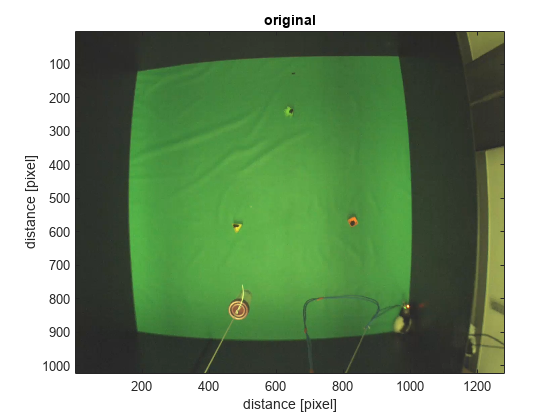

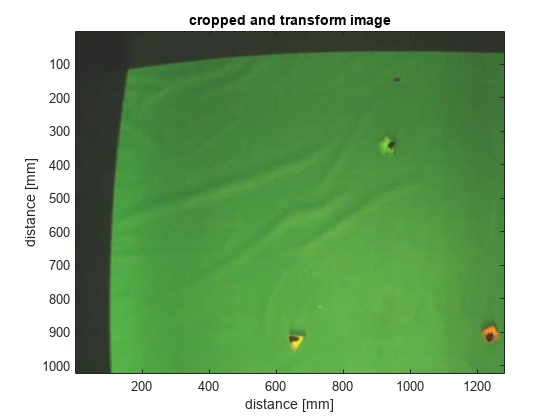

tracking = position_preprocessing_dlc('basepath',basepath,'forceReload',false,'project',project,'mazeSize',mazeSize);

## Get spikes

Detect spikes and times and assign them to the cluster they are coming. It will read the input file in the format of 'basename.amplifier_res.mat', where basename is the name of the recording (number-date-time). Inspect the script for more details on the different input parameters. 

% TODO: remove helper functions for waveforms 
spikes = loadSpikes_JRC('basepath',basepath,'forceReload',false);

loadSpikes: Loading JRClust data
Loading shank #1/2
Loading shank #2/2
Saving spikes.


## Get waveforms

**TODO:** include the new getWaveforms function.

The trough to peak of the waveform will be used as a criterion to select the place cells. Pyramical cells in the hippocampus, which are the place cell candidates are supposed to have a relatively broad waveform (>250us trough to peak). 

[~,basename] = fileparts(basepath);
if exist(fullfile(basepath,[basename,'.waveforms.cellinfo.mat'])) 
    load(fullfile(basepath,[basename,'.waveforms.cellinfo.mat']));
else
    data = load(fullfile(basepath,'amplifier_res.mat'), 'meanWfLocalRaw');
    wfmaxSite = data.meanWfLocalRaw(:,1,:);  % select channel with max amplitude 
    wfmaxSite = reshape(wfmaxSite,size(wfmaxSite,1),size(wfmaxSite,3));
    rawWaveforms = double(wfmaxSite).*(37.4./192);
    rawWaveforms = rawWaveforms';
    for unit = 1:size(wfmaxSite,2)
        waveforms(unit) = getWaveforms(rawWaveforms(unit,:),'basepath',basepath,'sample_rate',tracking.amplifier_sample_rate);
    end
    save(fullfile(basepath, [basename '.waveforms.cellinfo.mat']),'waveforms'); 
end

## Get firing rates 

The firing rate of each neuron for each position bin is calculated. This code is based on the buzcode script. Several parameters can be changed, such as the speedThresh (default = 0.1) and the nBins (default = 50). Inspect the script for more details. I am setting the speed threshold to 1 cm/s = 10 mm/s.

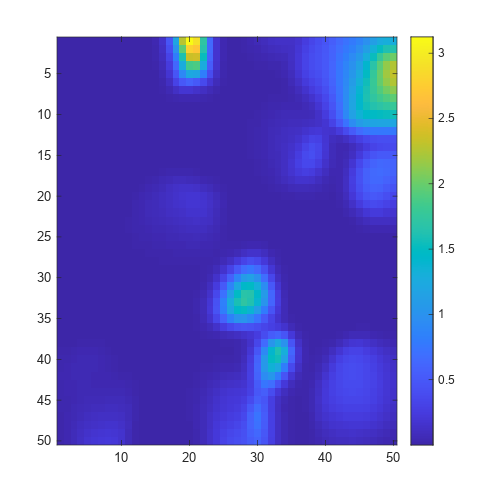

positions = [tracking.position.t, tracking.position.x, tracking.position.y];

firingMaps = bz_firingMapAvg_new(positions,spikes,'basepath',basepath,'forceReload',false,'saveMat',true,'speedThresh',10);

% Plot firing and trajectory maps 
if plotMaps
    plotFiringMaps(firingMaps,'basepath',basepath,'savePlot',true,'overwrite',true);
end


if plotTraj
    % this is quite slow
    plotTrajectoryFiring(spikes,tracking,'basepath',basepath,'mazeSize',mazeSize,'savePlot',true,'overwrite',true);
end

## Get spatial information content

This is defined as in [https://www.nature.com/articles/s41467-020-14611-7](https://www.nature.com/articles/s41467-020-14611-7) 

spatial_info = getSpatialInformation(firingMaps,'basepath',basepath);

## Get place fields 

The conditions that define a place field are related to the min and max size of the field relative to the size of the animal's experimental environment and the peak firing rate. For now, the function will only keep the first place field detected. 

[placeFieldsStats,mapStats] = getPlaceFields('firingMaps',firingMaps,'basepath',basepath,'geometry','2D',...
    'FRThres',[0.1,10],'IoUThres',0.5,'infoThres',0.5,'Peak2TroughThres',0.25,'forceReload',false);

Loading spatialInfo


file = struct with fields:
       name: '9_240229_163045.spatialInfo.cellinfo.mat'
     folder: 'D:\Rat_Recording\rEO_06\9_240229_163045'
       date: '04-Mar-2024 16:54:07'
      bytes: 2336
      isdir: 0
    datenum: 7.3932e+05

Loading waveforms


file = struct with fields:
       name: '9_240229_163045.waveforms.cellinfo.mat'
     folder: 'D:\Rat_Recording\rEO_06\9_240229_163045'
       date: '04-Mar-2024 16:51:58'
      bytes: 251504
      isdir: 0
    datenum: 7.3932e+05


if plotFields
    plotPlaceFields2D(firingMaps,mapStats,'basepath',basepath,'savePlot',true,'overwrite',true);
end